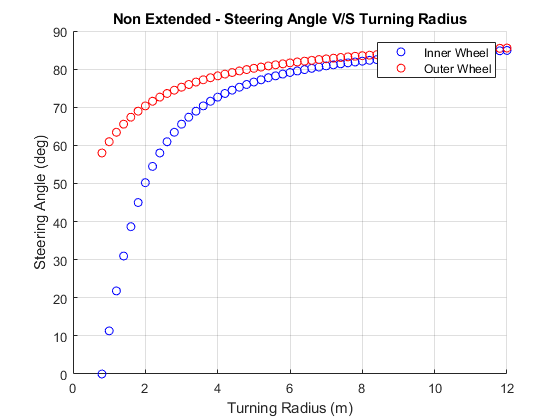

r = 0.8:0.2:12;
l = 2;
c = 1.6;
u_s = 1;
u_r = 0.2;


for i = 1:length(r)
    r_i = sqrt(((r-(c/2)).^2)+((l/2).^2));
    r_o = sqrt(((r+(c/2)).^2)+((l/2).^2));
    alpha_i = acosd((l/2)/r_i(i));
    alpha_o = acosd((l/2)/r_o(i));
    figure(1)
    hold on
    scatter(r(i),alpha_i,'blue')
    hold on
    scatter(r(i),alpha_o,'red')
end

hold off
xlabel('Turning Radius (m)')
ylabel("Steering Angle (deg)")
legend('Inner Wheel','Outer Wheel')
grid on
title('Non Extended - Steering Angle V/S Turning Radius')

jdakcnjsd

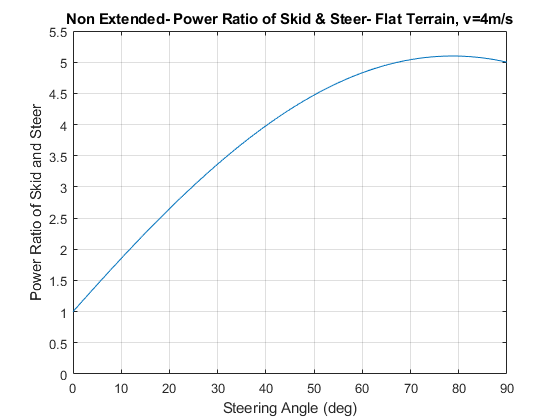

alpha = 0:0.25:90;
P_rat = cosd(alpha)+(sind(alpha)*(u_s/u_r));
plot(alpha, P_rat)
ylim([0 5.5])
xlabel('Steering Angle (deg)')
ylabel("Power Ratio of Skid and Steer")
grid on
title('Non Extended- Power Ratio of Skid & Steer- Flat Terrain, v=4m/s')